# Analyzing Electrocardiogram Data

This example shows how to do a simple analysis of an electrocardiogram (ECG) signal. The signal is a measure of electrical activity of the heart over time.

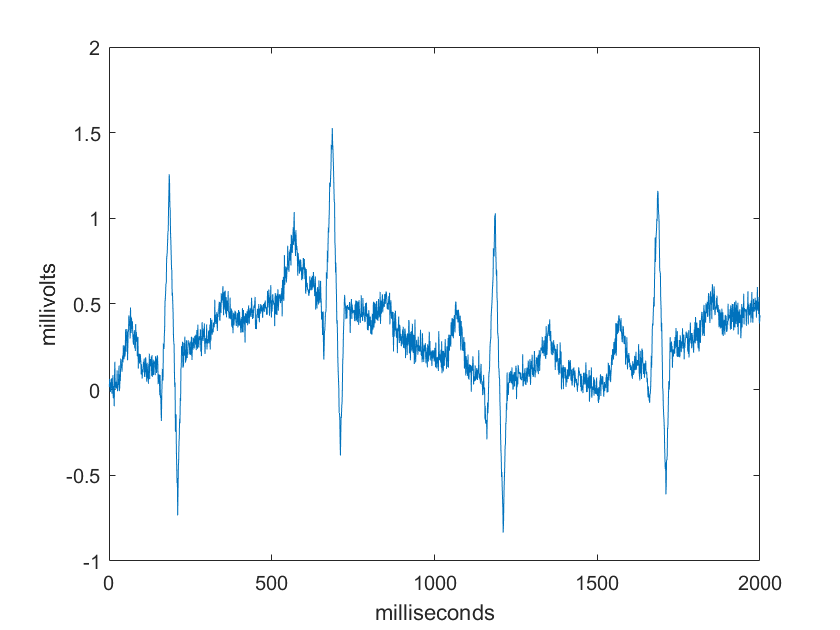

load noisyecg
plot(noisyECG)
xlabel('milliseconds')
ylabel('millivolts')

## Remove Trends in the Data

The signal is measured by electrodes attached to the skin and is sensitive to disturbances such as power source interference and noises due to movement.  The above signal shows a baseline shift and therefore does not represent the true amplitude. We can use the **Remove Trends **task to fit the baseline shift to a polynomial and remove it.

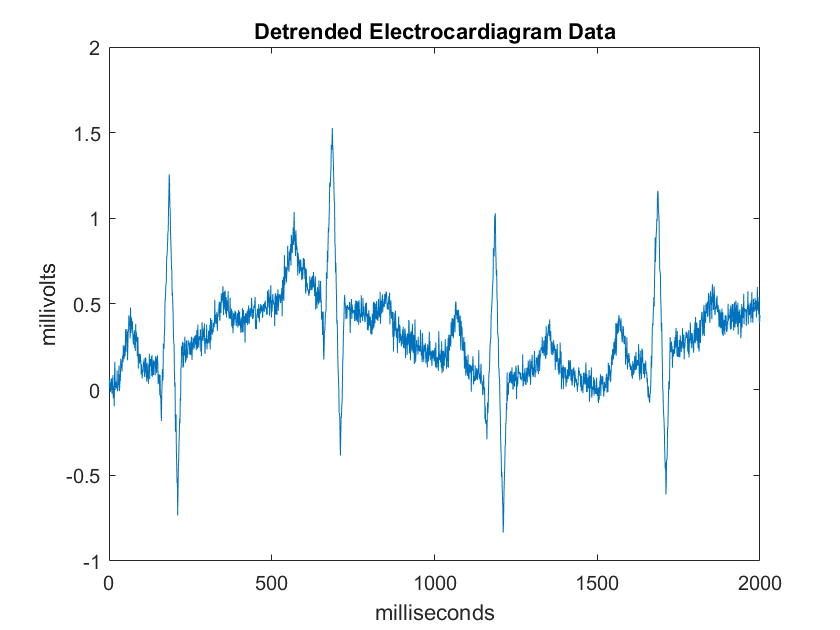

%Use a Live Task to detrend the signal
xlabel('milliseconds')
ylabel('millivolts')

title('Detrended Electrocardiagram Data')

## Find the R Wave Maximums

In an elecrocardiogram, the R wave it the large upward deflection in the signal that represents the deploarization of the main mass of the heart's ventricles.  The R-waves can be detected by thresholding peaks above 0.5mV.  We can use the Find Local Extrema task

%use a live task to identify the maxima
xlabel('milliseconds')
ylabel('millivolts')

## Calculate the Heart Rate

We can now calculate the heart rate from the time interval between R wave maximums.